# DC Microgrid Simulator

clear all
close all
clc

rng(7)

numOfDGs = 4;
threshold = 0.6;

## Generate a random physical topology

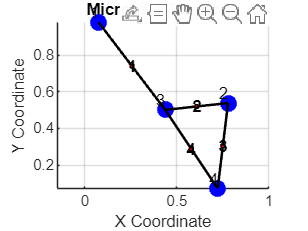

Coordinates of DGs:
    0.0763    0.9780
    0.7799    0.5385
    0.4384    0.5011
    0.7235    0.0721

Adjacency Matrix:
     0     0     1     0
     0     0     1     1
     1     1     0     1
     0     1     1     0

B_il Matrix:
     1     0     0     0
     0     1     1     0
    -1    -1     0     1
     0     0    -1    -1



% Input: numOfDGs and physicalDistanceThreshold

% I should be able to change "numOfDGs" and "numOfLines" variables freely
% see https://en.wikipedia.org/wiki/Random_geometric_graph
% https://github.com/shiran27/NetworkedSystemAnalysisAndControl/blob/main/Network.m
% particularly look at the function: loadARandomNetwork

% Generate a topology randomly
% Generate numOfDGs number of random points in R^2 spase using rand(1,2)
% If two generated points are closer to each other than a predefined
% threshold, they are assumed as connected. 

% Final output: of this code is B=[B_il]_{i,l} matrix and the numOfLines
% plot the graph like in Fig 2.
% A = [A_ij]_{i,j} is the adgacency matrix of the DG-DG topology (N\times N)
[coords, A_ij, B_il] = generatePhysicalTopology(numOfDGs, threshold);


%%%% Update the figure to show the assumed initial communication topology
% (A_ij matrix representa the communication topology)



## Generate Random set of DGs

% Initial parameter values for DGs
R0 = 0.05;      % Resistance
L0 = 0.01;      % Inductance
C0 = 0.0022;       % Capacitance % Decreasing this, increasing convergence speed - Global

RL0 = 5;      % Load Resistance
Y0 = 1/RL0;     % Load Conductance
% IL0 = 0.5;      % Constant Current Load
IL0 = 3;      % Constant Current Load
PL0 = 50;
CCL_Coefficient = 2;  % Constant Current Load Coefficient

Pn0 = 0.8;

LoadNoiseMean = 10;
LoadNoiseStd = 2;


for i = 1:1:numOfDGs
    DG{i} = GenerateDG(R0,L0,C0,RL0,IL0,Pn0,PL0,coords(i,:));
    
    [PVal, KVal, LVal, nuVal, rhoVal, status] = ComputePassivityForDGs(DG{i});
end


DG Specifications:
Source Voltage: 120.00 V
Reference Voltage: 48.00 V
Rated Current: 12.56 A
Power Rating: 800.00 W
Power Rating (Pn): 0.76 W
Current through Resistive Load: 10.08 A
Constant Current Load: 2.48 A
Power Losses (Resistance): 7.89 W
Power Losses (Switching): 30.14 W
Current Ripple: 0.22 A (1.8%)
Component Values:
 Inductance: 0.011 H
 Capacitance: 0.002 F
 Resistance: 0.050 Ω
 Load Resistance: 4.762 Ω

DG Specifications:
Source Voltage: 120.00 V
Reference Voltage: 48.00 V
Rated Current: 14.97 A
Power Rating: 1000.00 W
Power Rating (Pn): 0.87 W
Current through Resistive Load: 11.85 A
Constant Current Load: 3.12 A
Power Losses (Resistance): 9.92 W
Power Losses (Switching): 35.94 W
Current Ripple: 0.24 A (1.6%)
Component Values:
 Inductance: 0.010 H
 Capacitance: 0.003 F
 Resistance: 0.044 Ω
 Load Resistance: 4.050 Ω

DG Specifications:
Source Voltage: 120.00 V
Reference Voltage: 48.00 V
Rated Current: 12.81 A
Power Rating: 800.00 W
Power Rating (Pn): 0.76 W
Current through

## Generate Random Set of Lines

% Initial parameter values for Lines
Rl0 = 0.02;     % Line Resistance % Increasing this, the damping ratio decrease - Local
Ll0 = 0.01;     % Line Inductance

numOfLines = size(B_il,2);

for l = 1:1:numOfLines
    Line{l} = GenerateLine(Rl0,Ll0);
    [PBarVal, nuBarVal, rhoBarVal, status] = ComputePassivityForLines(Line{l});
end

Clear variables unrelated

 clearvars -EXCEPT DG Line numOfDGs numOfLines A_ij B_il coords adjMatrix CCL_Coefficient
 % global DG Line B_il A_ij % Making some values as global variables

## Co-Design Process

parameters

BarGamma = 1000;    % Fixed value for gammaBar
isSoft = 1;      % Set to 1 to avoid the hard graph constraint

% pScalar = 1/(numOfDGs+numOfLines);
piScalar = 10^-1;
plScalar = 10^-2;

piVals = piScalar*ones(1,numOfDGs);
plVals = plScalar*ones(1,numOfLines);

## 1. Centralized Local Controller Design

% Inside the function, you need to solve the LMI problem in (66) and add
% local passivity information and local controller information to the DG
% and Line variables. 

First Method: This Method computes the passivity indices for DGs and lines at the same time. 

[DG,Line,statusLocalController] = centralizedLocalControlDesign(DG,Line,B_il,BarGamma,piVals,plVals) % topologyMetrics may be the B matrix 

DG 1 matrix dimensions: Ai=3x3, Bi=3x1
DG 2 matrix dimensions: Ai=3x3, Bi=3x1
DG 3 matrix dimensions: Ai=3x3, Bi=3x1
DG 4 matrix dimensions: Ai=3x3, Bi=3x1

MOSEK Version 10.1.25 (Build date: 2024-2-14 13:14:18)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 684             
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 32              
  Matrix variables       : 56 (scalarized: 1248)
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1              

DG = 1×4 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


Line = 1×4 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


statusLocalController = logical
   1




DG{1}

ans = struct with fields:
    sourceVoltage: 120
       refVoltage: 48
    switchingFreq: 12500
     ratedCurrent: 12.5592
      powerRating: 800
     resonantFreq: 30.9510
    currentRipple: 0.2239
      dutyNominal: 0.4000
                R: 0.0500
                L: 0.0107
                C: 0.0025
                Y: 0.2100
               IL: 2.4791
                A: [3×3 double]
                B: [3×1 double]
      coordinates: [0.0763 0.9780]
               Pn: 0.7630
               PL: 47.8815
               P0: [3×3 double]
               K0: [-2.9243 0.2022 -2.2173]
               nu: -3.8608e-04
              rho: 2.5701e+03
      gammaTilde0: 8.7348e-04
            R_CPL: [3×3 double]
       lambda_CPL: 1.0000
        alpha_CPL: 7.6399
         beta_CPL: 9.3329


Line{1}

ans = struct with fields:
      R: 0.0211
      L: 0.0093
      A: -2.2769
      B: 108.0383
     P0: 0.0046
     nu: -0.0790
    rho: 0.0211


Second Method: This method first computes the DGs' passivity indices and use those properties to compute the Lines' passivity indices. 

% [DG, rhoTilde_i, nu_i, gammaTilde_i,statusDG] = designDGPassivity(DG, B_il,piVals);
% [Line, statusLine] = designLinePassivity(Line, DG, B_il, BarGamma, piVals,plVals,rhoTilde_i, nu_i);
%%%% Theoretically explain why this works in the paper, in a corollary (of Theorem 2).  
%%%% There is an imbalance

## 2. Global Controller Design

[DG,Line,statusGlobalController,gammaTildeVal,K,C,BarC,H,P_iVal,P_lVal] = globalControlDesign(DG,Line,A_ij,B_il,BarGamma,isSoft);

MOSEK Version 10.1.25 (Build date: 2024-2-14 13:14:18)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 2021            
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 4               
  Scalar variables       : 488             
  Matrix variables       : 10 (scalarized: 3728)
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - p

gammaTildeVal = 3.9759e-04

costFun0Val = 0.0100

%%%% Theoretically think about adding normalizing constraints trace(P_i)==1, trace(P_l)==1 constraint

K{1,1}

ans =      0     0     0
     0     0     0
     0     0     0


K{1,3}

ans = 1.0e+04 *

         0         0         0
         0    1.1837         0
         0         0         0


K{3,4}

ans =      0     0     0
     0     0     0
     0     0     0


K{1,2}

ans =      0     0     0
     0     0     0
     0     0     0



SS_Activation = 0.01;      % Steady State Control Input activation
LC_Activation = 0.01;      % Local Control Input activation
DC_Activation = 0.01;      % Distributed Control Input activation

% Initialized nominal and reference voltages
V_nom = 120;            % Nominal Voltage
V_ref = 48;             % Reference Voltage

% Scenario #1: Global Load Change
R_Global = 5;           % Global Load
ChangeGlobalLoad1 = 1;  % Connect Global Load #2
ChangeGlobalLoad2 = 3;  % Disconnect Global Load #2

% Scenario #1: Local Load Change
PlugOut = 3;            % Plug out Local load
PlugIn = 5;             % Plug in Local load

CPL_activation = 8;     % CPL activation


% % Scenario #3: Change of Reference Voltage:
% V_ref1 = 48;
% V_ref2 = 100;
% change_reference = 4;

## Generate Optimized Communication Topology

K{1,1} = 
     0     0     0
     0     0     0
     0     0     0

maxNorm = 0.0000000000
K{1,2} = 
     0     0     0
     0     0     0
     0     0     0

maxNorm = 0.0000000000
K{1,3} = 
   1.0e+04 *

         0         0         0
         0    1.1837         0
         0         0         0

maxNorm = 11836.8473343186
K{1,4} = 
   1.0e+03 *

         0         0         0
         0   -3.4880         0
         0         0         0

maxNorm = 3487.9901741987
K{2,1} = 
     0     0     0
     0     0     0
     0     0     0

maxNorm = 0.0000000000
K{2,2} = 
     0     0     0
     0     0     0
     0     0     0

maxNorm = 0.0000000000
K{2,3} = 
   1.0e+03 *

         0         0         0
         0    1.2878         0
         0         0         0

maxNorm = 1287.7598677463
K{2,4} = 
   1.0e+03 *

         0         0         0
         0    3.3389         0
         0         0         0

maxNorm = 3338.9081378687
K{3,1} = 
   1.0e+03 *

         0         0         0
    

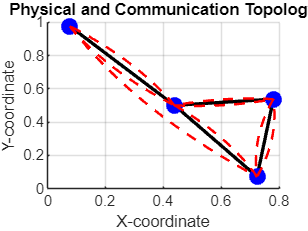

commMatrix =      0     0     1     1
     0     0     1     1
     1     1     0     0
     0     1     1     0


% Plot Communication Topology
[commMatrix] = generateCommunicationTopology(coords, A_ij, K)

#### The following functions are desgined to evaluate the effects of different parameters on the passivity indices of DGs and lines and their feasibilities

Optimize pVals (Method 1: Qucik and Dirty, Run this in a seperate .m file - to get faster result) 

% See the 'OptimizepValsMethod1.m' file. 

Optimize pVals (Method 2: Use Matlab 'fmincon')

% [piVals, plVals] = optimizeCodesignParameters()

Optimize pVals (Method 3)

% plotLocalControlDesign(DG, Line, B_il, BarGamma, numOfDGs, numOfLines);
% plotGlobalControlDesign(DG, Line, B_il, BarGamma, A_ij, isSoft, numOfDGs, numOfLines);
% plotCombinedControlDesign(DG, Line, B_il, BarGamma, A_ij, isSoft, numOfDGs, numOfLines);
% plotTestBothFeasibility(DG, Line, B_il, BarGamma, A_ij, isSoft, numOfDGs, numOfLines);

Function to evaluate the effect of number of DGs and Threshold

% numDGsRange = 5:6;              % Example range for number of DGs
% thresholdRange = 0.1:0.1:1;     % Example range for threshold values
% pScalarRange = 0.01:0.01:10;    % Example range for pScalar values
% BarGamma = 5;                   % Fixed value for gammaBar
% isSoft = 1;                     % Set to 1 to use soft constraint

% [numOfDGs, threshold] = evaluateDesigns(numDGsRange, thresholdRange, BarGamma, pScalarRange, isSoft);